# Laboratorio 2

## Mateo Fernández (202320768), Gabriela Villalba y Gabriel Sanchez (202420981)

## Punto 1.

%1.1
Vref = 5.000;
A = [5.210, 5.220, 5.210, 5.220, 5.210];
B = [4.910, 5.080, 5.000, 4.980, 5.030];

xS = single([1 1e3 1e8])
xD = double([1 1e3 1e8])
sesgo = media - Vref;
Ea = abs(media - Vref);
Er = Ea / abs(Vref);
Epct = 100 * Er;
end

[media_A, std_A, sesgo_A, Ea_A, Er_A, Epct_A] = calcular_metricas(A, Vref);
[media_B, std_B, sesgo_B, Ea_B, Er_B, Epct_B] = calcular_metricas(B, Vref);

%1.2

numero_medicion = 1:5;

figure

scatter(numero_medicion, A, 45, 'b', 'filled')
hold on
scatter(numero_medicion, B, 45, 'r', 'filled')
yline(Vref, 'k--', 'LineWidth', 1.5)
hold off

xlabel('Número de medición')
ylabel('Voltaje [V]')
title('Comparación de mediciones: Instrumento A vs B')
legend('Instrumento A', 'Instrumento B','V_{ref} = 5.000 V', 'Location', 'best')
grid on

%Tabla comparativa
nombres_columnas= {'Instrumento','Media','Desv_Std','Sesgo','Ea','Er','E_pct'};
tabla_metricas = table({'A';'B'}, [media_A;media_B], [std_A;std_B], [sesgo_A;sesgo_B], ...
    [Ea_A;Ea_B], [Er_A;Er_B], [Epct_A;Epct_B],'VariableNames',nombres_columnas)

%1.3
b_A = media_A - Vref;
A_corr= A - b_A;

[media_Acorr, std_Acorr, sesgo_Acorr, Ea_Acorr, Er_Acorr, Epct_Acorr] = calcular_metricas(A_corr, Vref);

tabla_metricas_corr = table({'A (original)';'A (corregida)'}, [media_A;media_Acorr], [std_A;std_Acorr], ...
    [sesgo_A;sesgo_Acorr], [Ea_A;Ea_Acorr], [Er_A;Er_Acorr], [Epct_A;Epct_Acorr], ...
    'VariableNames', {'Version','Media','Desv_Std','Sesgo','Ea','Er','E_pct'})

## Punto 2.

%a.
xS = single([1 1e3 1e8])
xD = double([1 1e3 1e8])

%b.
disp("Bytes ocupados por arreglo")
w1 = whos("xS")
w2 = whos("xD")
disp("Bytes por elemento" + newline + "xS")
w1_ele = w1.bytes/numel(xS)
disp("xD")
w2_ele = w2.bytes/numel(xD)

%c. 
disp("Separación local")
separacion_xS = eps(xS)
separacion_xD = eps(xD)

disp("Separación elemento a elemento")
separacion_s1 = single(eps(1))
separacion_s2 = single(eps(10^3))
separacion_s3 = single(eps(10^8))

separacion_d1 = double(eps(1))
separacion_d2 = double(eps(10^3))
separacion_d3 = double(eps(10^8))

%d.
disp("Minimos y máximos dependiendo del tipo de variable")
min_d = realmin("double")
max_d = realmax("double")
flint_d = flintmax("double")

min_s = realmin("single")
max_s = realmax("single")
flint_s = flintmax("single")

%e.
T = table( ...
    string({class(xS); class(xD)}), ...
    [w1_ele; w2_ele], ...
    [min_s; min_d], ...
    [max_s; max_d], ...
    [flint_s; flint_d], ...
    [single(eps(1)); double(eps(1))], ...
    [single(eps(10^3)); double(eps(10^3))], ...
    [single(eps(10^8)); double(eps(10^8))], ...
    'VariableNames', ...
    ["clase", "bytes", "realmin", "realmax", "flintmax", ...
     "eps(1)", "eps(10^3)", "eps(10^8)"] ...
);
T
%2.2

a = 10^16;
b = -10^16;
c = 1;
format long
f1_s = single(0.1+0.2-0.3)
f1_d = double(0.1+0.2-0.3)
f2_s = single(sin(pi))
f2_d = double(sin(pi))
f3_s = single((a+b)+c)
f3_d = double((a + b) + c)
f4_s = single(a+(b+c))
f4_d = double(a+(b+c))

% Identifique específicamente qué propiedad algebraica deja de observarse
%exactamente en el ejemplo con a, b y c

%2.3

alpha = 2.5*single(1.42*10^38)
beta = 2.5*double(1.42*10^38)

%Compare el resultado con realmax('single') y realmax('double') 
%obtenidos en 2.1 y determine si ocurre desbordamiento

%{
Análisis requerido. Explique con datos de 2.1 por qué el espaciado entre números representables
aumenta al crecer la magnitud y por qué un cálculo puede comportarse de manera diferente en
single y double
%}

## Punto 3.

## Punto 4.

## Punto 5.

V = 12 + 0.01*d(8)
R = 220 + 0.5*d(9)
delta_v = 0.005*(1+d(7)/10) %COTAS MAXIMAS DEL ERROR ABSOLUTO
delta_r = 0.2 + 0.05*d(8)

function potencia = calcular_potencia(V, R)
    potencia = V*V/R;
end





## Punto 6.

**Evaluación de la corrección lineal de errores de ganancia y offset en un ADC de 12 bits para mejorar la conversión de voltaje**

Sistema estudiado: Conversión análoga-digital (ADC) en los microcontroladores F2810/F2811/F2812

Magnitud medida o calculada: Código ADC representando el voltaje de entrada

Instrumento o algoritmo utilizado: ADC + calibración de ganancia y offset de dos puntos

Valor de referencia o especificación disponible: Entradas de voltaje de referencia

Cusa del error descrita en la fuente: Errores en el offset y ganancia del ADC

Un ADC ideal de 12 bits sin error de ganancia ni offset se describe como:

$x_{ideal} = \frac{4095}{3.0V} \cdot mi \cdot V_{in}$ donde $y$ = Conteo de salida, $x$ = Voltaje de entrada  $mi =  1.0 $ equivalente a la ganancia ideal.

Es decir, el ADC se comporta como una función afin traduciendo el rango $[0V,3V]$ a un conteo digital equivalente dentro del rango$[0,4095]$

No obstante, la familia de microcontroladores exhiben un error de ganancia y offset definidos por:

$x_{med} = ma \cdot x_{ideal} + b$ donde $ma$ y $b$ son la ganancia real y el offset real respectivamente.

Para producir los datos necesarios para establecer una corrección, se utilizará el siguiente caso propuesto en la hoja de datos:

$x_{med} =  1.05x_{ref}+80$, lo que ilustra un error de ganancia del $5\%$ y un offset del conteo del$1.95\%$

A partir de esta relación se genera la siguiente tabla de datos    

xref = [0; 500; 1000; 1500; 2000];

xmed = 1.05*xref + 80;

calculation = compose("1.05(%g) + 80", xref);

T = table((1:5)', xref, calculation, xmed, ...
    'VariableNames', {'Point', 'x_ref', 'Calculation_x_meas', 'x_med'});

T

T = 5×4 table
    Point    x_ref    Calculation_x_meas    x_med
    _____    _____    __________________    _____

      1         0     "1.05(0) + 80"          80 
      2       500     "1.05(500) + 80"       605 
      3      1000     "1.05(1000) + 80"     1130 
      4      1500     "1.05(1500) + 80"     1655 
      5      2000     "1.05(2000) + 80"     2180 


%Sin corrección
%Error absoluto
e_abs_pre = abs(xref-xmeas)

e_abs_pre =     80
   105
   130
   155
   180


%Error maximo
e_max_pre = max(e_abs_pre)

e_max_pre = 180

%Error absoluto medio
e_mae_pre = 1/numel(e_abs_pre)*sum(e_abs_pre)

e_mae_pre = 130

%RMSE
e_rmse_pre = sqrt(1/numel(e_abs_pre)*sum(e_abs_pre.^2))

e_rmse_pre = 134.7219

La hoja de datos propone obtener los parámetros de calibración explotando el comportamiento lineal del error. Para esto se toman dos datos de entrada de referencia conocidos, $x_L$ y $x_H$, y se registran sus respectivos conteos de salida del ADC, $y_L$ y $y_H$. Con estos dos pares de datos se calcula la ganancia real del ADC calculando su pendiente $m_a = \frac{y_H-y_L}{x_H-x_L}$ y reorganizando la ecuación representando los errores de medición se puede encontrar el offset $b = y_L -x_L \cdot m_a$. Una vez identificadas, se puede realizar una estimación corregida del valor de entrada a partir de cualquier conteo medido $y$. Despejando $x$ de la función de transferencia se obtiene: $x_{corr} = \frac{y - b}{m_a}$.

La hoja de datos presenta la corrección mediante una ganancia y un offset de calibración $x_{corr} = y \cdot \text{CalGain} - \text{CalOffset}$ donde $\text{CalGain} = \frac{1}{m_a}$ y $\text{CalOffset} = \frac{b}{m_a}$. A partir de esta estrategia se corrigen los dos errores del ADC el error de ganancia, culpable de un cambio en la pendiente de la conversión, y, el error de offset, el cual desplaza el conteo de salida incluso teniendo entradas de $V_{in} = 0$.

%Corrección

% Puntos de referncia de calibración
xL = xref(1);
yL = xmeas(1);

xH = xref(end);
yH = xmeas(end);

% Ganancia y offset reales
ma = (yH - yL) / (xH - xL);
b = yL - xL*ma;

% Constantes de calibración
CalGain = (xH - xL) / (yH - yL);
CalOffset = yL*CalGain - xL;

% Valores corregidos
xcorr = xmeas*CalGain - CalOffset;

% Error absoluto
e_abs_post = abs(xref - xcorr);

% Máximo error absoluto
e_max_post = max(e_abs_post)

e_max_post = 5.6843e-14


% Error absoluto medio (MAE)
e_mae_post = mean(e_abs_post)

e_mae_post = 1.1369e-14


% RMSE
e_rmse_post = sqrt(mean((xref - xcorr).^2))

e_rmse_post = 2.5421e-14


% Mejoria
mejora_rmse = 100*(1 - e_rmse_post/e_rmse_pre)

mejora_rmse = 100.0000


T_corr = table(xref, xmeas, xcorr, e_abs_post, ...
    'VariableNames', ...
    {'x_ref', 'x_meas', 'x_corr', 'Erro absoluto'});

T_corr

T_corr = 5×4 table
    x_ref    x_meas    x_corr    Erro absoluto
    _____    ______    ______    _____________

       0        80         0               0  
     500       605       500      5.6843e-14  
    1000      1130      1000               0  
    1500      1655      1500               0  
    2000      2180      2000               0  


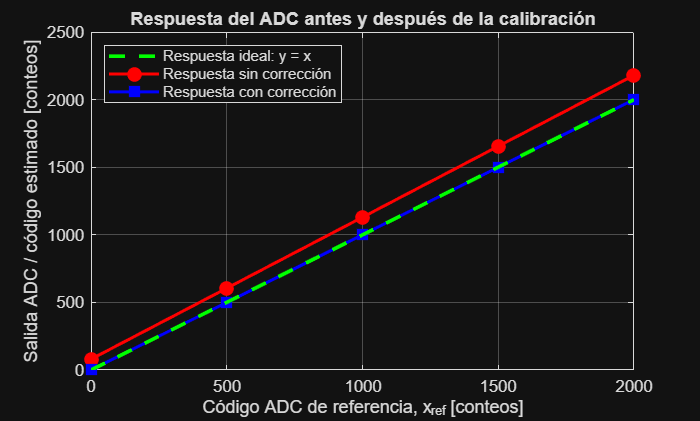

figure; hold on;

h_meas = plot(xref, xmeas, 'ro-', ...
    'LineWidth', 1.8, ...
    'MarkerFaceColor', 'r', ...
    'MarkerSize', 7);

h_corr = plot(xref, xcorr, 'bs-', ...
    'LineWidth', 1.8, ...
    'MarkerFaceColor', 'b', ...
    'MarkerSize', 7);

h_ideal = plot(xref, xref, 'g--', ...
    'LineWidth', 2.2);

grid on;
box on;

xlabel('Código ADC de referencia, x_{ref} [conteos]');
ylabel('Salida ADC / código estimado [conteos]');
title('Respuesta del ADC antes y después de la calibración');

legend([h_ideal h_meas h_corr], ...
    {'Respuesta ideal: y = x', ...
     'Respuesta sin corrección', ...
     'Respuesta con corrección'}, ...
    'Location', 'northwest');